## ECMA418_2/shmAuditoryFiltBank.m

% cross_check_shmAuditoryFiltBank.m  –  fully-log frequency axis
fs       = 48e3;
duration = 1.0;
x        = randn(fs*duration,1);

% Run filter bank and get the figure
y = shmAuditoryFiltBank(x,true);   % the function already uses semilogx

% Make sure the figure is logarithmic (belt-and-braces)
figHandles = findall(0,'Type','axes');
for ax = figHandles.'
    set(ax, 'XScale','log');       % enforce log-frequency axis
end


% Save first ½-Bark band for listening / numeric comparison
band1 = y(:,1);
band1 = band1 ./ max(abs(band1)) * 0.99;   % -0.9 dBFS
audiowrite('band01.wav',band1,fs);

disp('Done: log-axis plots refreshed and “band01.wav” written.');

Done: log-axis plots refreshed and “band01.wav” written.


## ECMA418_2/shmBasisLoudness.m

rng(0)  % Make results reproducible

%% Constants (duplicated from ECMA‑418‑2:2024)
DELTA_F0 = 81.9289;
C        = 0.1618;

%% 2‑D input (single half‑Bark band — Bark = 9 → index 18)
hb_idx      = 9.0;                                     % half‑Bark value
centre_freq = (DELTA_F0/C) * sinh(C * hb_idx);         % exact ECMA value ~1027.025 Hz

sig2d = randn(1024, 8) * 0.02;  % ~60 dB SPL noise
[rect2d, loud2d, rms2d] = shmBasisLoudness(sig2d, centre_freq);

fprintf("2‑D test sizes: rect [%s], loud [%s], rms [%s]\n", ...
        num2str(size(rect2d)), num2str(size(loud2d)), num2str(size(rms2d)));

2‑D test sizes: rect [1024     8], loud [1  8], rms [1  8]


fprintf("2‑D loudness ≥ 0: %d\n", all(loud2d(:) >= 0));

2‑D loudness ≥ 0: 1



%% 3‑D input (full 53 bands)
sig3d = randn(1024, 8, 53) * 0.02;
[rect3d, loud3d, rms3d] = shmBasisLoudness(sig3d);

fprintf("3‑D test sizes: rect [%s], loud [%s], rms [%s]\n", ...
        num2str(size(rect3d)), num2str(size(loud3d)), num2str(size(rms3d)));

3‑D test sizes: rect [1024     8    53], loud [1   8  53], rms [8  53]


fprintf("3‑D loudness ≥ 0: %d\n", all(loud3d(:) >= 0));

3‑D loudness ≥ 0: 1



%% Assertions (fail early on problems)
assert(isequal(size(rect2d), size(sig2d)) && isequal(size(rect3d), size(sig3d)), ...
       "Rectified signal sizes do not match inputs");
assert(min(loud2d(:)) >= 0 && min(loud3d(:)) >= 0, ...
       "Negative values detected in basis loudness");

disp("Basic sanity checks passed.");

Basic sanity checks passed.


## ECMA418_2/shmNoiseRedLowPass.m

clc; clear; close all;

fs = 48e3;                   % 48 kHz sample rate
T  = 0.5;                    % duration [s]
t  = 0:1/fs:T-1/fs;          % time vector (row)

% Generate test signal: 6 kHz sine at -6 dBFS plus white noise at -20 dBFS
f0   = 6e3;
ampS = 0.5;                  % -6 dBFS ~= 0.5
ampN = 0.1;                  % -20 dBFS ~= 0.1

tone  = ampS * sin(2*pi*f0*t);
noisy = tone + ampN * randn(size(t));

% Run the Sottek low‑pass noise‑reduction filter
clean = shmNoiseRedLowPass(noisy.', fs);  % function expects column vector

% Plot
figure('Name', 'ECMA‑418‑2 low‑pass noise reduction (MATLAB demo)');
plot(t, noisy, 'DisplayName', 'Noisy input', 'Color', [0.6 0.6 0.6]); hold on;
plot(t, clean, 'LineWidth', 1.2, 'DisplayName', 'Filtered output');
legend; xlabel('Time [s]');
title('ECMA‑418‑2 low‑pass noise reduction (MATLAB demo)');
grid on; box on;

## ECMA418_2/shmOutMidEarFilter.m

clear;  clc;

%% 1. Generate a 1-s white-noise probe @ 48 kHz
fs   = 48e3;
rng(0, "twister");                % reproducible noise
x    = randn(fs, 1);              % 48 000 samples

%% 2. Run the outer-/middle-ear filter (free-frontal + plot)
y_ff = shmOutMidEarFilter( x, "free-frontal", true );

%% 3. Optional: run the diffuse-field variant too (no plot)
y_df = shmOutMidEarFilter( x, "diffuse", false );

%% 4. Print a simple level sanity check
fprintf("Processed %d samples\n", numel(y_ff));
fprintf("RMS  in : %.3f  |  free-frontal out : %.3f  |  diffuse out : %.3f\n", ...
        rms(x), rms(y_ff), rms(y_df));

## ECMA418_2/shmPreProc.m

clear, clc

% -------------------------------------------------------------------------
% Load the Python-generated test vectors
d  = load('shm_preproc_test.mat');     % gives x_py and y_py (column vectors)
x  = d.x_py(:);                        % ensure column orientation
y_py = d.y_py(:);

% -------------------------------------------------------------------------
% Run the MATLAB original with the same parameters
blockSize = 2048;
hopSize   = 1024;
y_mat = shmPreProc(x, blockSize, hopSize, true, true);

% -------------------------------------------------------------------------
% Compare
fprintf('Shapes: MATLAB = %d × %d,  Python = %d × %d\n', ...
        size(y_mat,1), size(y_mat,2), size(y_py,1), size(y_py,2));

diff = max(abs(y_mat - y_py));
fprintf('Max |Δ| between outputs = %.3g\n', diff);

if diff < 1e-12
    disp('✅  MATLAB and Python outputs are identical to floating-point precision.');
else
    disp('⚠️  Difference detected! Check your ports / parameters.');
end

## shmResample.m

% sanity_check_shmResample.m
% --------------------------------------------
% 1.  Read the original WAV file
file_read = [basepath_SQAT 'sound_files' filesep 'reference_signals' filesep 'ExSignal_A320_auralized_departure_104dBFS.wav'];
[inSignal, fsIn] = audioread(file_read);

% 2.  Resample to 48 kHz with your function
[outSignal, fsOut] = shmResample(inSignal, fsIn);

% 3.  Write the resampled audio to disk
outputFile = 'output_48k.wav';
audiowrite(outputFile, outSignal, fsOut);        % fsOut should be 48 000

% 4.  Read the file back in to verify the header
[~, fsVerify] = audioread(outputFile);

% 5.  Display the three rates
fprintf('Original fs : %d Hz\n', fsIn);
fprintf('shmResample : %d Hz\n', fsOut);
fprintf('WAV header  : %d Hz\n', fsVerify);

## shmRoughLowPass.m

spec = [0   0  ;
        1   0.5;
        0.5 0.2;
        1.2 0.1];

out = shmRoughLowPass(spec, 50, 0.02, 0.10)

size(out)

## shmRoughWeight.m

modRate = linspace(1, 300, 500);
modfreqMaxWeight = 70;
alphaVec = 1.5 * ones(size(modRate));
betaVec  = 0.8 * ones(size(modRate));
roughWeightParams = [alphaVec; betaVec];
w = shmRoughWeight(modRate, modfreqMaxWeight, roughWeightParams);
fprintf('First five weights: %s\n', mat2str(w(1:5), 6));

First five weights: [0.000583724 0.00123772 0.00206063 0.00303261 0.00414077]


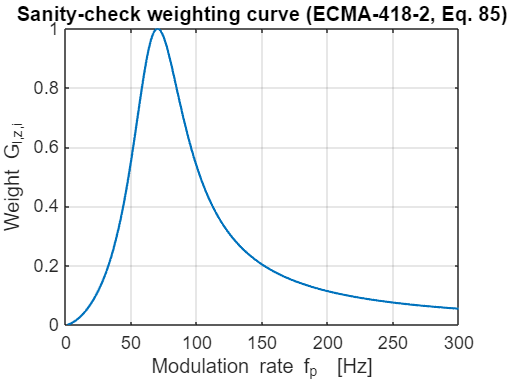


figure
plot(modRate, w, 'LineWidth', 1.2)
xlabel('Modulation rate f_p  [Hz]')
ylabel('Weight G_{l,z,i}')
title('Sanity-check weighting curve (ECMA-418-2, Eq. 85)')
grid on

## shmSignalSegments.m

fs      = 48e3;                 % sampling rate
t       = (0 : 1/fs : 0.5-1/fs)'; % 0.5 s time vector, column
x       = [sin(2*pi*440*t), ... % left  channel: 440 Hz
           sin(2*pi*880*t)];    % right channel: 880 Hz
[blocks, idx] = shmSignalSegment(x, 1, 4096, 0.75, 1, false);

disp('Size of blocks array:');

Size of blocks array:


disp(size(blocks));

        4096          43           2



disp('First few block-start indices:');

First few block-start indices:


disp(idx(1:min(4,end)))  

           1        1025        2049        3073

